Note page II. 6

**NOTE**: Change the objective function at bottom of the code

clc;clear all; 
figure; hold on;

a=0;                            % start of interval
b=2;                            % end of interval
epsilon=0.000001;               % accuracy value
iter= 10;                       % maximum number of iterations
tau=double((sqrt(5)-1)/2);      % golden proportion coefficient, around 0.618
k=0;                            % initialize number of iterations count

fprintf(' L = b-a = %g', b-a);

 L = b-a = 2

fprintf('The first x1:')

The first x1:

x1=a+(1-tau)*(b-a)            % computing x values

x1 = 0.7639

fprintf('The first x2:')

The first x2:

x2=a+tau*(b-a)

x2 = 1.2361

fprintf('Evalucated at point x1')

Evalucated at point x1

f_x1=f(x1)                     % computing values in x points

f_x1 = -6.0820

fprintf('Evalucated  at  point x2')

Evalucated  at  point x2

f_x2=f(x2)

f_x2 = -5.5836


plot(x1,f_x1,'rx')              % plotting x
plot(x2,f_x2,'rx')



while ((abs(b-a)>epsilon) && (k<iter))
    fprintf('##########Iteration # %g ##########', k+1)
    if(f_x1<f_x2)
        fprintf('evaluated value at point x2 was larger.')
        fprintf('new b:')
        b=x2
        fprintf('new x2:')
        x2=x1
        fprintf('new x1:')
        x1=a+(1-tau)*(b-a)
        
        fprintf('Evaluated at new x1:')
        f_x1=f(x1)
        fprintf('Evaluated at new x2:')
        f_x2=f(x2)
        
        plot(x1,f_x1,'rx');
    else
        fprintf('evaluated value at point x1 was larger.')        
        fprintf('new a:')
        a=x1
        fprintf('new x1:')
        x1=x2
        fprintf('new x2:')
        x2=a+tau*(b-a)
        
        fprintf('Evaluated at new x1:')
        f_x1=f(x1)
        fprintf('Evaluated at new x2:')
        f_x2=f(x2)
        
        plot(x2,f_x2,'rx')
    end
    
    k=k+1;
end

##########Iteration # 1 ##########

evaluated value at point x2 was larger.

new b:

b = 1.2361

new x2:

x2 = 0.7639

new x1:

x1 = 0.4721

Evaluated at new x1:

f_x1 = -5.8390

Evaluated at new x2:

f_x2 = -6.0820

##########Iteration # 2 ##########

evaluated value at point x1 was larger.

new a:

a = 0.4721

new x1:

x1 = 0.7639

new x2:

x2 = 0.9443

Evaluated at new x1:

f_x1 = -6.0820

Evaluated at new x2:

f_x2 = -6.0466

##########Iteration # 3 ##########

evaluated value at point x2 was larger.

new b:

b = 0.9443

new x2:

x2 = 0.7639

new x1:

x1 = 0.6525

Evaluated at new x1:

f_x1 = -6.0272

Evaluated at new x2:

f_x2 = -6.0820

##########Iteration # 4 ##########

evaluated value at point x1 was larger.

new a:

a = 0.6525

new x1:

x1 = 0.7639

new x2:

x2 = 0.8328

Evaluated at new x1:

f_x1 = -6.0820

Evaluated at new x2:

f_x2 = -6.0880

##########Iteration # 5 ##########

evaluated value at point x1 was larger.

new a:

a = 0.7639

new x1:

x1 = 0.8328

new x2:

x2 = 0.8754

Evaluated at new x1:

f_x1 = -6.0880

Evaluated at new x2:

f_x2 = -6.0800

##########Iteration # 6 ##########

evaluated value at point x2 was larger.

new b:

b = 0.8754

new x2:

x2 = 0.8328

new x1:

x1 = 0.8065

Evaluated at new x1:

f_x1 = -6.0884

Evaluated at new x2:

f_x2 = -6.0880

##########Iteration # 7 ##########

evaluated value at point x2 was larger.

new b:

b = 0.8328

new x2:

x2 = 0.8065

new x1:

x1 = 0.7902

Evaluated at new x1:

f_x1 = -6.0870

Evaluated at new x2:

f_x2 = -6.0884

##########Iteration # 8 ##########

evaluated value at point x1 was larger.

new a:

a = 0.7902

new x1:

x1 = 0.8065

new x2:

x2 = 0.8166

Evaluated at new x1:

f_x1 = -6.0884

Evaluated at new x2:

f_x2 = -6.0887

##########Iteration # 9 ##########

evaluated value at point x1 was larger.

new a:

a = 0.8065

new x1:

x1 = 0.8166

new x2:

x2 = 0.8228

Evaluated at new x1:

f_x1 = -6.0887

Evaluated at new x2:

f_x2 = -6.0886

##########Iteration # 10 ##########

evaluated value at point x2 was larger.

new b:

b = 0.8228

new x2:

x2 = 0.8166

new x1:

x1 = 0.8127

Evaluated at new x1:

f_x1 = -6.0886

Evaluated at new x2:

f_x2 = -6.0887

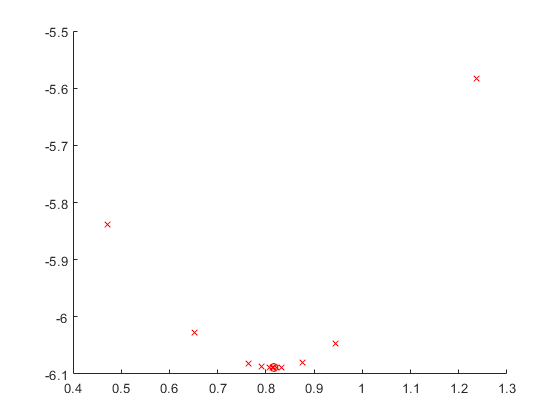

ans = 'x_min=0.816554'

ans = 'f(x_min)=-6.088662 '

%%%%might have to use this %%%%%%%%%%%%%%%%%%%%%%%%%%
% x star = (b+a)/2
% f(x star)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%Not this below%%%%%%%% see page II 6 last line%%%%%%%

% chooses minimum point
if(f_x1<f_x2)
    sprintf('x_min=%f', x1)
    sprintf('f(x_min)=%f ', f_x1)
    plot(x1,f_x1,'ro')
else
    sprintf('x_min=%f', x2)
    sprintf('f(x_min)=%f ', f_x2)
    plot(x2,f_x2,'ro')
end

function y=f(x)
% modify this - write your own function!
y=x^3-2*x-5;
end
